# LK Setup

## Convex Polyhedra $$\mathcal{U},\mathcal{Z}$, $\mathcal{C}$$

    clear;
    % Table 1: Parameters For LK Simulation
        %Vehicle Parameters for LK Mode
        [M,Iz,a,b,Cf,Cr,v0]=deal(1650,2315.3,1.11,1.59,133000,98800,25);
        [um,rdm,ym,vm,psim,rm]=deal(pi/6,0.25,0.9,10,10,10);
        %Tunable Parameters in CLF-CBF-QP
        [c3,gamma0,beta0,beta1,T]=deal(0.2,0.2,1,1,0.1);

    %Modeling
        %Lane Keeping Model
            A=[0,1,v0,0;
               0,-(Cf+Cr)/(M*v0),0,(b*Cr-a*Cf)/(M*v0)-v0;
               0,0,0,1;
               0,(b*Cr-a*Cf)/(Iz*v0),0,-(a^2*Cf+b^2*Cr)/(Iz*v0)];
            B=[0 0;Cf/M 0;0 -1;a*Cf/Iz 0];
        %Dimensions
            [nx,nz,nu]=deal(4,1,1);
        %Dicrete system
            dsys=c2d(ss(A,B,eye(nx),zeros(nx,nu+nz)),T,'zoh');
            [Ak,Bk]=deal(dsys.A,dsys.B);

    [Pu,Px,Pz]=deal(Polyhedron([-1;1],[um;um]),Polyhedron([eye(nx);-eye(nx)],kron([1;1],[ym;vm;psim;rm])),Polyhedron([-1;1],[rdm;rdm]));

## Sample $\(U_0, X_0, Z_0,X_1\)$

(1) Collect data to form $\(U_0, X_0, Z_0,X_1\)$.

        t=20; % Data length
        [U0,X0,X1,Z0]=deal(zeros(nu,t),zeros(nx,t),zeros(nx,t),zeros(nz,t));

        for i=1:t
            [U0(:,i),X0(:,i),Z0(:,i)]=deal(Pu.randomPoint,Px.randomPoint,Pz.randomPoint);
            X1(:,i)=Ak*X0(:,i)+Bk*[U0(:,i);Z0(:,i)];
        end

(2) Full-row Rank Condition

    %Select partial Datas
    if rank([U0;X0;Z0;ones(1,t)])~=nu+nx+nz+1||rank(X1)~=nx, error('Failed to satisfy Full-row Rank Condition!'); end

## Construct $\mathcal{X}
$

    Xf=Algorithm2ConstructRecursiveFeasibleSet(U0,X0,Z0,X1,Pu,Px,Pz)

Iteration:1
Iteration:2
Iteration:3
Iteration:4
Iteration:5
Iteration:6
Iteration:7
Polyhedron in R^4 with representations:
    H-rep (irredundant) : Inequalities  66 | Equalities   0
    V-rep (redundant)   : Vertices 215 | Rays   0
Functions : none


## Parameters of Control Algorithm 1

%Parameters
    [Xf,Pu,Px,C,P,U0,X0,Z0,X1]=deal(Xf,Pu,Polyhedron('A',[-1 0 0 0;1 0 0 0],'b',[ym;ym]),[1 0 0 0],[1 0 0 0]'*[1 0 0 0],U0,X0,Z0,X1);       
%Tunable Parameters
    [c3,gamma0,beta0,beta1]=deal(c3,gamma0,beta0,beta1);
%Simulation time=Count*T=5 seconds, rk=0 means lane center
    [Count,rk]=deal(50,0);

#### 1) All vertices of $\mathcal{X}\otimes \mathcal{Z}$ with Constraints for Recursive Feasibility

[xData0, uData0]=computeVerticesData(Xf,Pu,Px,C,P,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,Ak,Bk,rdm,rk,Count,1);

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

[xData1,uData1]=computeVerticesData(Xf,Pu,Px,C,P,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,Ak,Bk,-rdm,rk,Count,1);

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

#### 2) All vertices of $\mathcal{X}\otimes \mathcal{Z}$ without Constraints for Recursive Feasibility

[xData2,uData2]=computeVerticesData(Xf,Pu,Px,C,P,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,Ak,Bk,rdm,rk,Count,0);

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

[xData3,uData3]=computeVerticesData(Xf,Pu,Px,C,P,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,Ak,Bk,-rdm,rk,Count,0);

正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

# *Save all datas*

save File

# Draw LK

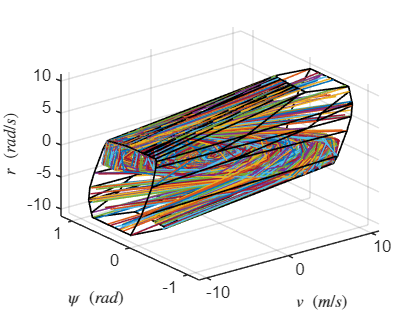

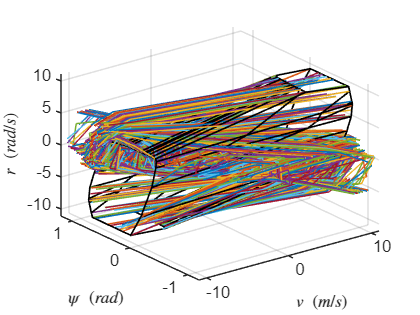

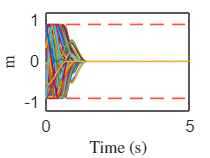

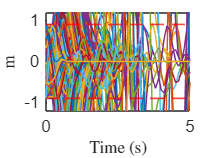

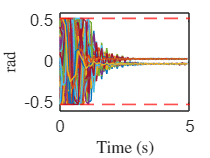

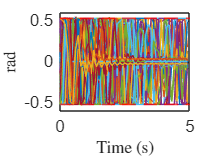

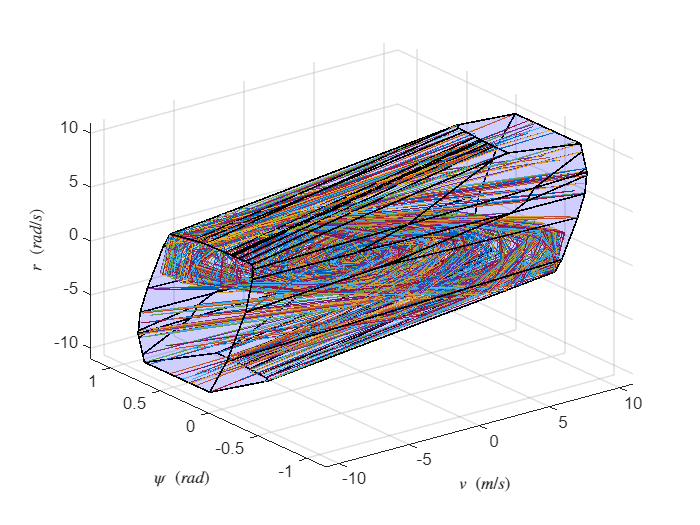

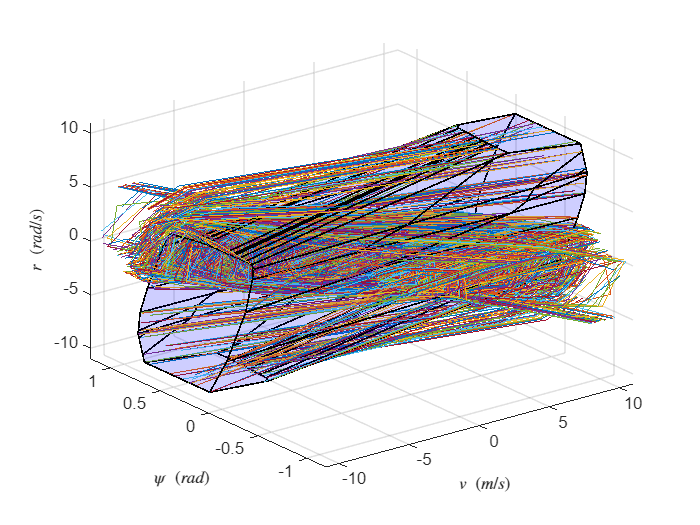

run('LK_Draw.mlx')